# This MATLAB live script provides details of modeling and analysis of the benchmark **72-bar truss **optimization problem.

**By: **Mohammad Farshchin, Ph.D.

**Email: **Mohammad.Farshchin@gmail.com

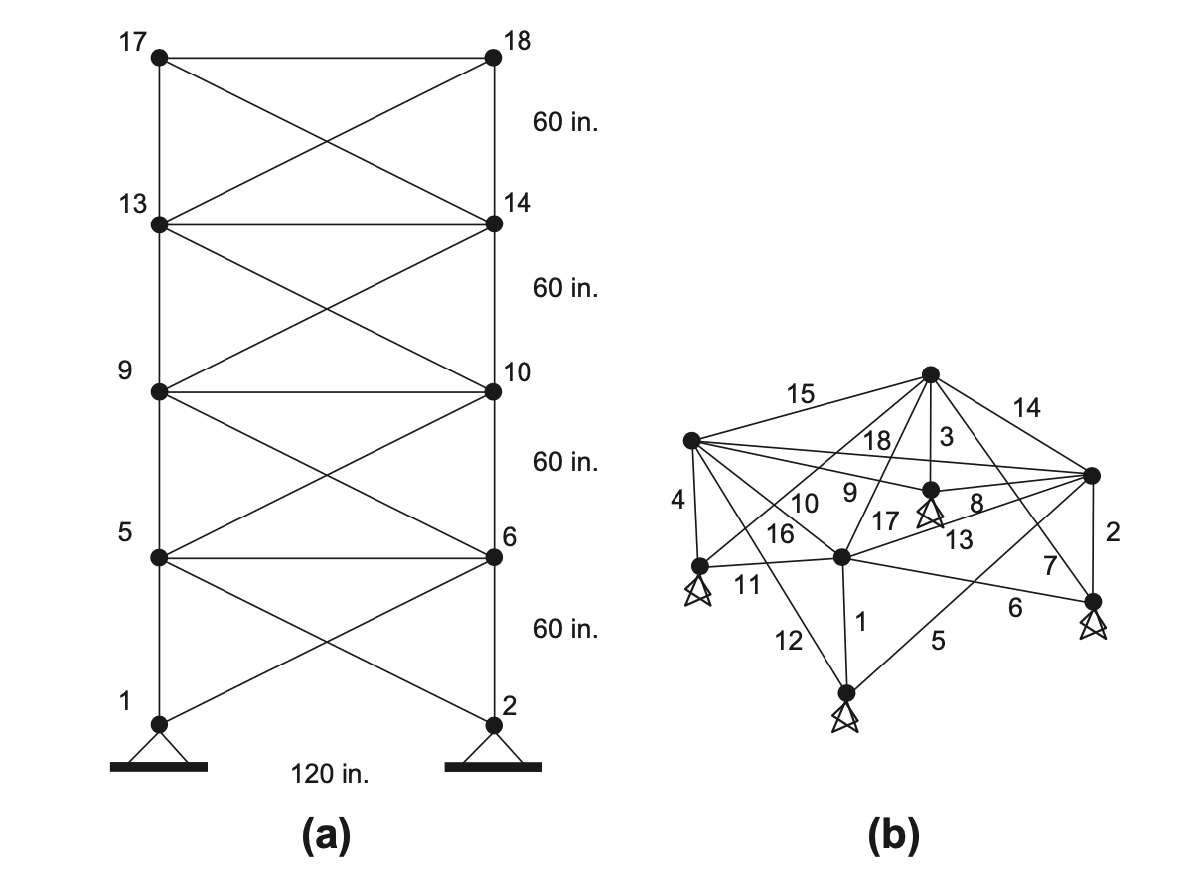

### **For detailed information about this benchmark problem refer to the following paper:**

- Camp, C.V. & Farshchin, M. (2014). [Design of space trusses using modified teaching-learning based optimization](http://www.sciencedirect.com/science/article/pii/S0141029614000236), Engineering Structures 62-63, 87-97

### **Please also refer to the following publications for information about several optimization algorithms to optimize this problems:**

- Farshchin, M., Maniat, M., Camp, C.V., & Pezeshk, S. (2018). [School based optimization algorithm for design of steel frames](https://www.sciencedirect.com/science/article/pii/S0141029617308787), Engineering Structures, Volume 171, 326-335.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Multi-class teaching–learning-based optimization for truss design with frequency constraints](http://www.sciencedirect.com/science/article/pii/S0141029615006732), Engineering Structures, Volume 106, 1, 355-369.

- Farshchin, M., Camp, C.V., & Maniat, M. (2016). [Optimal design of truss structures for size and shape with frequency constraints using a collaborative optimization strategy](https://www.sciencedirect.com/science/article/pii/S0957417416304900), Expert Systems with Applications, Vol 66.

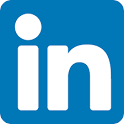 [https://www.linkedin.com/in/mfarshchin/](https://www.linkedin.com/in/mfarshchin/)          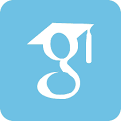 [https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en](https://scholar.google.com/citations?user=ZYO6CwEAAAAJ&hl=en)

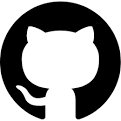 [https://github.com/mfarshchin](https://github.com/mfarshchin)                         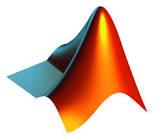 [https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin](https://www.mathworks.com/matlabcentral/profile/authors/3727592-mohammad-farshchin)

## 72-bar truss problem with continuous design variables

Configuration of the 72-bar benchmark truss is shown in the figure above. For additional details please refere to [this](http://www.sciencedirect.com/science/article/pii/S0141029614000236) publication.

**Important note:** members of this truss are grouped into 16 groups. Also there are two load combination for this design optimization problem.

**Main scripts for modeling and analysis:** 

- **DisData25.m  **Properties of 25-bar truss (e.g. geometry, loading, boundary conditions, penalty function, etc) with discrete design variables are defined in this function 

- **ST25D.m** This function is to run the analysis for a 25-bar truss with discrete design variables

The following set of commands are to run the 25-bar truss for a randomly generated design

clear
D=Data72; % Define the truss (geometry, connectivity, etc)
ConDesign=[1.88, 0.52, 0.10, 0.10, 1.28, 0.52, 0.10, 0.10,...
    0.54, 0.52, 0.10, 0.10, 0.16, 0.55, 0.41, 0.58]; % Define a random design (section area for each group of elements)
fprintf('Random design vector is: \n\n'),disp(ConDesign)

Random design vector is: 

  Columns 1 through 15

    1.8800    0.5200    0.1000    0.1000    1.2800    0.5200    0.1000    0.1000    0.5400    0.5200    0.1000    0.1000    0.1600    0.5500    0.4100

  Column 16

    0.5800



Assign this desing to the elements in each group.

for J=1:size(D.Group,1)
    Design(D.Group{J},:)=ConDesign(J);
end

Now we can run the analysis

% Analyze the design and compte the total weight of truss (Weight, lbs) and objective value (penalized weight) 
[Weight,Objective]=ST72(Design,D);
% print the design
fprintf('Truss Design is: \n\n'),disp(Design')

Truss Design is: 

  Columns 1 through 15

    1.8800    1.8800    1.8800    1.8800    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200    0.1000    0.1000    0.1000

  Columns 16 through 30

    0.1000    0.1000    0.1000    1.2800    1.2800    1.2800    1.2800    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200    0.5200

  Columns 31 through 45

    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.5400    0.5400    0.5400    0.5400    0.5200    0.5200    0.5200    0.5200    0.5200

  Columns 46 through 60

    0.5200    0.5200    0.5200    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1600    0.1600    0.1600    0.1600    0.5500    0.5500

  Columns 61 through 72

    0.5500    0.5500    0.5500    0.5500    0.5500    0.5500    0.4100    0.4100    0.4100    0.4100    0.5800    0.5800



fprintf('Truss weight is: %6.4f lbs\n',Weight);

Truss weight is: 383.0572 lbs


fprintf('Penalized weight (Objective value) is: %6.4f\n',Objective);

Penalized weight (Objective value) is: 383.0572


Note: for details of penalty function check out the Data72.m file